# Лабораторна робота 3

# Відновлення зображень

clear; close all; clc;

## 1-2. Завантаження зображення з бібліотеки MATLAB та його відображення

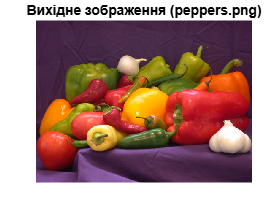

I = im2double(imread('peppers.png'));

figure;
imshow(I);
title('Вихідне зображення (peppers.png)');

## 3-4. Перекручення(змазання) зображення, змінюючи параметри LEN і THETA та його відображення

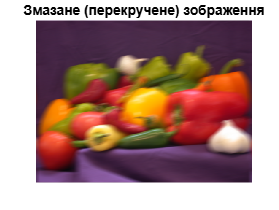

LEN = 19;     % Довжина розмиття
THETA = 10;   % Кут розмиття

% PSF (Point Spread Function) - ядро згортки, що відповідає розмиттю під час руху
PSF = fspecial('motion', LEN, THETA);

% Згортка зображення з PSF:
blurred = imfilter(I, PSF, 'conv', 'circular');
% 'conv' означає згортку, 'circular' — граничні умови (зображення повторюється циклічно)

figure;
imshow(blurred);
title('Змазане (перекручене) зображення');

## 5-6. Відновлення зображення

Відновлення вихідного зображення за його змазаним спостереженням здійснюється шляхом “зворотної згортки”, тобто процедури, зворотної до дії спотворюючого фактора (у даному випадку – руху камери). Відновлення засобами MATLAB здійснюється з використанням функції **deconvwnr** (деконволюція – зворотна згортка), синтаксис

**deconvwnr(A, PSF, SNR);**

**A – **“змазане” зображення, 

**PSF - **фільтр, що характеризує перекручення,

**SNR –** відношення шум/сигнал у моделі перекручення

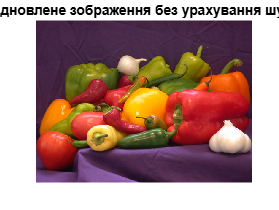

% SNR = 0 тому, що шуму немає, або він дуже малий, тому можемо його не враховувати.
wnr1 = deconvwnr(blurred, PSF, 0);

figure;
imshow(wnr1);
title('Відновлене зображення без урахування шуму');

## 7. Зашумлення початкового зображення та повторення пунктів 2-6

Для зашумлення використовував нормальний(гаусівський) білий шум

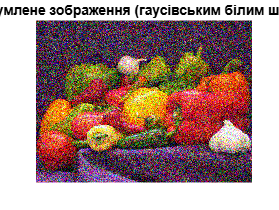

noisy = imnoise(I, 'gaussian', 0, 0.05);  

figure;
imshow(noisy);
title('Зашумлене зображення (гаусівським білим шумом)');

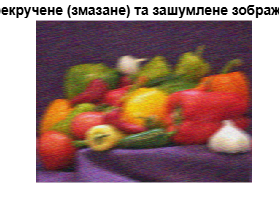


noisy_blurred = imfilter(noisy, PSF, 'conv', 'circular');

figure;
imshow(noisy_blurred);
title('Перекручене (змазане) та зашумлене зображення');

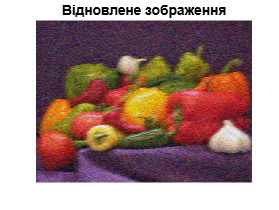


wnr2 = deconvwnr(noisy_blurred, PSF, 0.05);

figure;
imshow(wnr2);
title('Відновлене зображення');

## 8. Відповіді на питання:

### **1.** **Поясніть процес формування зображення. **

Процес формування зображення полягає у перетворенні реального об’єкта у його цифрову або аналогову візуальну репрезентацію за допомогою певної оптичної системи. На практиці отримане зображення є перекрученою версією оригіналу через фізичні обмеження реальних пристроїв (наприклад, камери або сенсори).

З математичної точки зору, формування зображення можна представити як дію оператора перекручень **Ξ** на оригінальне зображення **u(ν,υ)**, у результаті чого отримуємо спостережуване зображення **s(x,y).**

### **2. Опишіть модель формування зображень та лінійних перекручень.**

У більшості випадків системи формування зображень можна вважати **лінійними** та **інваріантними до зсувів**, тобто перекручення є однаковими для всіх точок зображення.

У такій моделі перекручення описуються **згорткою** вихідного зображення з **імпульсною характеристикою** системи (PSF – Point Spread Function), тобто:

`z(x,y) = u(x,y) ⊗⊗ h(x,y)`

Крім перекручень, зображення також зазвичай містить **адитивний шум** **n(x,y)**, тому повна модель виглядає так:

`s(x,y) = z(x,y) + n(x,y) = u(x,y) ⊗⊗ h(x,y) + n(x,y)`

У дискретному вигляді це означає, що кожен піксель спотвореного зображення — це зважена сума сусідніх пікселів оригінального зображення плюс шум.

### **3. Поясніть процес відновлення перекрученого зображення.**

Процес відновлення зображення — це зворотна задача до формування: за наявним перекрученим зображенням **s(x,y)** потрібно оцінити оригінал **u(x,y)**.

За відсутності шуму та при відомому фільтрі перекручень **h(x,y)**, можна скористатися **зворотною згорткою (деконволюцією)**:

`U = H⁻¹ * Z`

У MATLAB для цього використовується функція: **deconvwnr(blurred, PSF, SNR)**

де:

- `blurred` — спостережуване (змазане) зображення,

- `PSF` — фільтр, що описує перекручення (наприклад, рух камери),

- `SNR` — співвідношення сигнал/шум.